syms x(t) 
syms g h xo dxo real;
Dx = diff(x);

ode = diff(x,t,2) == g/h*x;

cond1 = x(0) == xo;
cond2 = Dx(0) == dxo;

conds = [cond1 cond2];


% Solve for symbolic solutions;

xSolu(t) = dsolve(ode,conds);
xSolu = simplify(xSolu)

$$xSolu(t) = \frac{{\mathrm{e}}^{\frac{t\,\sqrt{g\,h}}{h}}\,\left(\mathrm{dxo}\,h+\mathrm{xo}\,\sqrt{g\,h}\right)}{2\,\sqrt{g\,h}}-\frac{{\mathrm{e}}^{-\frac{t\,\sqrt{g\,h}}{h}}\,\left(\mathrm{dxo}\,h-\mathrm{xo}\,\sqrt{g\,h}\right)}{2\,\sqrt{g\,h}}$$

dxSol = diff(xSolu)

$$dxSol(t) = \frac{{\mathrm{e}}^{\frac{t\,\sqrt{g\,h}}{h}}\,\left(\mathrm{dxo}\,h+\mathrm{xo}\,\sqrt{g\,h}\right)}{2\,h}+\frac{{\mathrm{e}}^{-\frac{t\,\sqrt{g\,h}}{h}}\,\left(\mathrm{dxo}\,h-\mathrm{xo}\,\sqrt{g\,h}\right)}{2\,h}$$


T = solve(xSolu + xo, t, 'Real', true, "ReturnConditions",true);
T.conditions

$$ans = \begin{array}{l} 0<\sigma_{1}\wedge \mathrm{dxo}\,h+\mathrm{xo}\,\sqrt{g\,h}\neq 0\wedge \frac{\log\left(\sigma_{1}\right)}{\sqrt{g\,h}}\in \mathbb{R}\wedge \mathrm{dxo}\,h\neq \mathrm{xo}\,\sqrt{g\,h}\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{dxo}\,h-\mathrm{xo}\,\sqrt{g\,h}}{\mathrm{dxo}\,h+\mathrm{xo}\,\sqrt{g\,h}} \end{array}$$

T.t

$$ans = \frac{h\,\log\left(\frac{\mathrm{dxo}\,h-\mathrm{xo}\,\sqrt{g\,h}}{\mathrm{dxo}\,h+\mathrm{xo}\,\sqrt{g\,h}}\right)}{\sqrt{g\,h}}$$

% Solve for numerical solutions;

xo_num  = -0.05;
dxo_num = 0.28;
g_num   = 9.8;
h_num   = 0.85;

xSol_num = subs(xSolu,[xo, dxo, g, h],[xo_num, dxo_num, g_num, h_num])

$$xSol\_num(t) = -\frac{5\,\sqrt{833}\,{\mathrm{e}}^{-\frac{2\,\sqrt{833}\,t}{17}}\,\left(\frac{\sqrt{833}}{200}+\frac{119}{500}\right)}{833}-\frac{5\,\sqrt{833}\,{\mathrm{e}}^{\frac{2\,\sqrt{833}\,t}{17}}\,\left(\frac{\sqrt{833}}{200}-\frac{119}{500}\right)}{833}$$

dxSol_num = diff(xSol_num)

$$dxSol\_num(t) = \frac{10\,{\mathrm{e}}^{-\frac{2\,\sqrt{833}\,t}{17}}\,\left(\frac{\sqrt{833}}{200}+\frac{119}{500}\right)}{17}-\frac{10\,{\mathrm{e}}^{\frac{2\,\sqrt{833}\,t}{17}}\,\left(\frac{\sqrt{833}}{200}-\frac{119}{500}\right)}{17}$$


Ts = solve(xSol_num + xo_num, t , 'Real', true)

$$Ts = \frac{\sqrt{833}\,\log\left(-\frac{5\,\sqrt{833}+238}{5\,\sqrt{833}-238}\right)}{98}$$

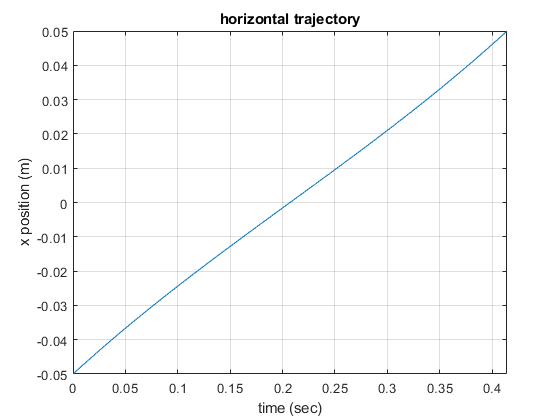

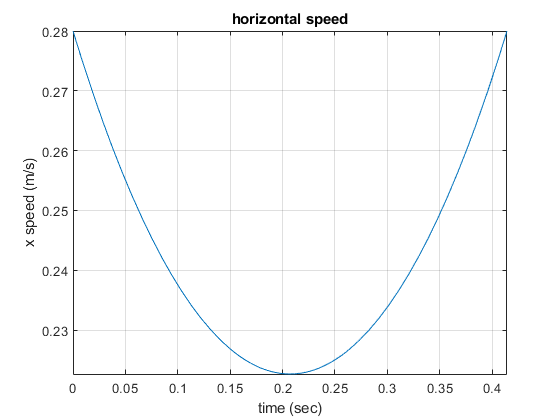

if ~isempty(Ts)
    figure
    fplot(xSol_num, [0 double(Ts)])
    grid on
    title('horizontal trajectory')
    xlabel('time (sec)');
    ylabel('x position (m)')
    
    figure
    fplot(dxSol_num, [0 double(Ts)])
    grid on
    title('horizontal speed')
    xlabel('time (sec)');
    ylabel('x speed (m/s)')
end   

## Run for loop to find feasible combinations of initial conditions

% Solve for numerical solutions;

xo_num  = linspace(-0.2,0,10);
dxo_num = linspace(0,0.5,10);
g_num   = 9.8;
h_num   = 0.85;

LIPsol = cell(10,10);

for j = 1:10
    for k = 1:10
        xSol_num = subs(xSolu,[xo, dxo, g, h],[xo_num(j), dxo_num(k), g_num, h_num]);
        dxSol_num = diff(xSol_num);
        Ts = solve(xSol_num + xo_num(j), t , 'Real', true);
        if ~isempty(Ts)
           LIPsol{j,k}= struct('xo',xo_num(j),'dxo',dxo_num(k),'Ts',double(Ts), 'dxa',-2*xo_num(j)/double(Ts),...
               'xSol',xSol_num,'dxSol',dxSol_num);
        end
    end
end

disp(LIPsol)

  Columns 1 through 9

              []              []              []              []              []              []              []              []              []
              []              []              []              []              []              []              []              []              []
              []              []              []              []              []              []              []              []              []
              []              []              []              []              []              []              []              []              []
              []              []              []              []              []              []              []    [1×1 struct]    [1×1 struct]
              []              []              []              []              []              []    [1×1 struct]    [1×1 struct]    [1×1 struct]
              []              []              []              []              []    [1×1 struct]    [1×1 st